**Predicting the Biodegradability of Chemicals from QSAR Data**

**Muzhaffar Maruf Ibrahim**

**230118670**

Load the data set to MATLAB

load QSAR_data.mat % load the QSAR_data.mat

**Data Processing**

Based on the Coursework brief, QSAR_data.mat in each row correspond to a specific chemical with 41 feature represented in the first 41 Columns. The last column in the data table is the label, which "1" indicate biodegradability and "0" indicate non-biodegradbility.

Thus, we would seperate the data based on the feature and the label. 

- Divide the data feature and data label

X_QSAR = QSAR_data(1:end,1:end-1) % 41 feature of 1055 chemicals

X_QSAR =     3.9190    2.6909         0         0         0         0         0   31.4000    2.0000         0         0         0    3.1060    2.5500    9.0020         0    0.9600    1.1420         0         0         0    1.2010         0         0         0         0    1.9320    0.0110         0         0    4.4890         0         0         0         0    2.9490    1.5910         0    7.2530         0         0
    4.1700    2.1144         0         0         0         0         0   30.8000    1.0000    1.0000         0         0    2.4610    1.3930    8.7230    1.0000    0.9890    1.1440         0         0         0    1.1040    1.0000         0         0         0    2.2140   -0.2040         0         0    1.5420         0         0         0         0    3.3150    1.9670         0    7.2570         0         0
    3.9320    3.2512         0         0         0         0         0   26.7000    2.0000    4.0000         0         0    3.2790    2.5850    9.1100         0    1.009

Y_QSAR = QSAR_data(end,1:end) % Biodegradability and non-biodegradbility label (0 and 1)

Y_QSAR =     5.0760    2.6588    2.0000         0         0         0    4.0000   54.5000         0         0         0         0    3.7920    0.6730   10.3270         0    1.0030    1.0890         0         0         0    1.3640    2.0000         0    1.0000         0    2.3630   -0.0010         0         0    2.1060         0    2.0000         0         0    4.0090    2.2060         0    9.1300         0    2.0000         0


- Check if there's any missing value and Infinite Value which represented by "NaN" and "Inf".

Missing_data = isnan(QSAR_data); % Check if there's any missing data
Inf_data = isinf(QSAR_data); % Check if there's any infinite value;

Sum_Miss_data = sum(Inf_data,"all"); % Sum all of the detected "inf" data
Sum_Inf_data = sum(Missing_data,"all"); % Sum all of the detected "Nan" data
 

disp(['The Total of Missing data is ',num2str(Sum_Miss_data)]) % Display the number "Nan" data

The Total of Missing data is 0


disp(['The Total of Inf data is ',num2str(Sum_Inf_data)]) % Display the number of "Inf" data

The Total of Inf data is 0


- Create a new dataset by identifying and removing duplicate values.

[~, index] = unique(QSAR_data, 'rows', 'stable'); % Retrive the index of unique rows

Duplicated_Rows = QSAR_data(setdiff(1:end,index), :); % Find duplicated rows with finding the indices of duplicated rows

disp("Rows with occurance more than 1 time:") % Display duplicated rows which occur more than 1 time

Rows with occurance more than 1 time:


disp(Duplicated_Rows);

    4.3430    3.9399         0         0         0         0         0   33.3000         0    4.0000         0   -2.5140    3.0470    1.5000    9.3090    4.0000    1.0900    1.1390         0         0         0    1.1080         0         0         0         0    2.0000   -0.0970         0   19.1070    2.6820         0         0         0    2.0000    3.5190    4.1670         0    8.0160         0         0    1.0000
    4.9830    4.2631         0         0         0         0         0   23.1000    2.0000    6.0000         0         0    3.3420    1.7920   10.0740    8.0000    1.0440    1.1600         0         0         0    1.0110         0         0         0         0    2.2470   -0.0080         0         0    2.6660         0         0         0    6.0000    3.3970    3.6940         0    7.8800         0         0    1.0000
    5.9980    1.8789    6.0000         0         0    3.0000         0   44.4000         0    1.0000         0    0.6420    4.3080    0.7490   11.6370    3.00


QSAR_data_new = unique(QSAR_data,"rows","stable"); % Establish a new data without any duplicate rows 

disp("New QSAR Data after delete the duplicated value:") % Display new data set without any duplicated rows

New QSAR Data after delete the duplicated value:


disp(QSAR_data_new) % Display new data set without any duplicated rows

    3.9190    2.6909         0         0         0         0         0   31.4000    2.0000         0         0         0    3.1060    2.5500    9.0020         0    0.9600    1.1420         0         0         0    1.2010         0         0         0         0    1.9320    0.0110         0         0    4.4890         0         0         0         0    2.9490    1.5910         0    7.2530         0         0    1.0000
    4.1700    2.1144         0         0         0         0         0   30.8000    1.0000    1.0000         0         0    2.4610    1.3930    8.7230    1.0000    0.9890    1.1440         0         0         0    1.1040    1.0000         0         0         0    2.2140   -0.2040         0         0    1.5420         0         0         0         0    3.3150    1.9670         0    7.2570         0         0    1.0000
    3.9320    3.2512         0         0         0         0         0   26.7000    2.0000    4.0000         0         0    3.2790    2.5850    9.1100        


X_QSAR_new = QSAR_data_new(1:end,1:end-1); % Define a new data feature with non-duplicated data
Y_QSAR_new = QSAR_data_new(1:end,end);% Define a new data label with non-duplicated data


- Construct the Principal Component Analysis     

    for i = 1:size(X_QSAR_new, 2) 
        X_QSAR_new(:, i) = zscore(X_QSAR_new(:, i))'; % Mean-Centering each range of Feature data between [0,1]
    end
        
    [coeff,score,latent]=pca(X_QSAR_new); % Initialize Principal Component Analysis to the data
    Chosen_PC = score(:,1:22) % Extracting 22 Principal Components

Chosen_PC =    -3.5800   -1.0089    0.2922    0.9156    0.3374    1.5223    1.1539   -0.5534   -0.1435   -0.6157    0.0669   -0.0965   -0.7890   -0.4972   -0.0901    0.1317   -0.1649   -0.3059   -0.2817    0.2912    0.0635    0.0739
   -3.4521   -0.7677    0.3682   -0.0853   -0.5410    0.0834   -0.2886    0.0462   -0.2975   -0.1123   -0.2252   -1.3591   -0.6926   -0.1444    0.0244   -0.0534   -0.0982   -0.0081    0.3384   -0.5916    0.0567   -0.7994
   -3.3417    1.1423    0.0216    0.8780    1.0762    0.8543    0.9259   -0.3077   -0.2124   -0.3347   -0.5687   -0.0512   -0.5872   -0.0128   -0.5410    0.1080    0.4426   -0.1413    0.3721   -0.2892   -0.1804    0.1819
   -6.1201    1.8376    0.0361   -3.0906    2.1200   -2.6157   -0.3689   -0.8254   -0.6627   -0.7453    0.8157    6.4893   -3.0519    0.8132   -0.6453    0.1682    0.6149    0.9558    0.6452   -0.6113   -1.0597    0.7872
   -2.4096    1.2918   -0.2457    1.6377    1.0620    0.7677    0.9925   -0.8346   -0.2835   -0.3033   -

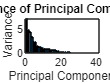

    
    figure
    
    % Plot the variances of the principal components
    bar(latent) 
    title('Variance of Principal Components') 
    xlabel('Principal Component')
    ylabel('Variance')   

- Proportion of Biodegdarable and Non-Biodegradable Label in the data

    tabulate(Y_QSAR_new) % Count the proportion of Biodegradable and Non-biodegradable label

  Value    Count   Percent
      0      698     66.35%
      1      354     33.65%


    count0 = sum(Y_QSAR_new == 0); % Sum all of the label "0" in the last column
    count1 = sum(Y_QSAR_new == 1); % Sum all of the label "1" in the last column

    chart = [count0 count1]; % Put the number of "0" and "1" label in the chart cell 

chart =    698   354


    labels = ["Non-Biodegradable","Biodegradable"]; % Label the each class quantity

labels = 1×2 string array
    "Non-Biodegradable"    "Biodegradable"


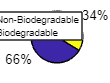


    pie(chart) % Creating Pie Chart to visualize the distribution of Label
   
    lgd = legend(labels); % Create legend

**Methodology**

- **Logistic Regression **

X = X_QSAR_new; % Define the features of the data
Y = Y_QSAR_new; % Define the labels of the data

theta = zeros(size(X, 2), 1); % Initialize theta as a column vector of zeros
max_iterations = 100; % Set the maximum number of iterations
epsilon = 1e-6; % Set a small convergence criterion
lambda = 1e-6; % Set L2 Regularization
k = 5; %Set 5 Fold Cross Validation

indices = crossvalind('Kfold',Y,k); % Create indices for each fold of Cross Validation
accuracy = zeros(k,1); % Initiate 5*1 space cell to fill accuracy for each cell

% Initialize arrays to store the predicted and actual labels for the best hyperparameters
predicted_labels = []; % Initiate Predicted Labels cell
actual_labels = []; % Initiate Actual Labels cell
probabilities_predicted = []; % Initiate Probabilities_Predicted Cell
probabilities_actual = []; % Initiate Probabilities_actual cell


% Seperate each division of Training and Test data for 5-Fold Cross Validation 
for i = 1:k
    test = (indices == i); 
    train = ~test;
    X_Train = X(train,:);
    X_Test = X(test,:);
    Y_Train = Y(train,:);
    Y_Test = Y(test,:);

    X_Train = [ones(size(X_Train, 1), 1), X_Train]; % Add bias term for X_train
    X_Test = [ones(size(X_Test, 1), 1), X_Test]; % Add bias term for X_test

    theta = zeros(size(X_Train,2),1); % Initialize Parameter for each fold

    % Newton-Raphson Method
    for iteration = 1:max_iterations
        z = X_Train * theta; % Calculate the logistic function values
        sigmoid = exp(z) ./ (1 + exp(z)); % Establish the sigmoid function
        W = diag((1 - sigmoid).*sigmoid); % Calculate the diagonal matrix W(theta)     
        gradient = X_Train' * (Y_Train - sigmoid);% Calculate the gradient of the logistic loss        
        Hessian = X_Train' * W * X_Train + lambda * eye(size(X_Train, 2)); % Calculate the Hessian matrix with Regularization
        delta_theta = inv(Hessian)*gradient; % Update theta using the Newton-Raphson update rule
        theta = theta + delta_theta; % Update the current theta
                
        if norm(delta_theta) < epsilon % Check for convergence
            break;
        end
    end

    z_test = X_Test * theta; % Implement trained paramater to the Test Data for each k fold 
    z_prob = exp(z_test) ./ (1 + exp(z_test)); % Implement model coeffecient to the sigmoid function
    z_pred = double(z_prob >= 0.5); % classify z_pred as 1 if the z_prob >= 0.5, otherwise 0
   
    predicted_y{i} =  z_pred; % predicted labels in k-fold
    actual_y{i} = Y_Test; % actual labels in k-fold
    probabilities_predicted = [probabilities_predicted; predicted_y{i}]; % Append the predicted labels in to a cell
    probabilities_actual = [probabilities_actual; actual_y{i}]; % Append the actual labels in to a cell

    predicted_labels = [predicted_labels; predicted_y{i}]; % Store the predicted labels for this fold
    actual_labels = [actual_labels; actual_y{i}]; % Store the actual labels for this fold
    
    correct_prediction = sum(z_pred == Y_Test); % Calculate the correct prediction which compared with label data 
    accuracy(i) = correct_prediction/length(Y_Test); % Calculate the accuracy of the prediction
    
    disp(['For fold ', num2str(i),', ', 'regularization: ', num2str(lambda),',', ' Accuracy: ', num2str(accuracy(i))]); % Display the k-fold, regularization, and Accuracy for each fold
end

For fold 1, regularization: 1e-06, Accuracy: 0.85714
For fold 2, regularization: 1e-06, Accuracy: 0.88095
For fold 3, regularization: 1e-06, Accuracy: 0.87143
For fold 4, regularization: 1e-06, Accuracy: 0.87678
For fold 5, regularization: 1e-06, Accuracy: 0.83886


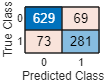


    cm_Logit = confusionchart(actual_labels,predicted_labels); % Initialize Confusion Matrix for Logistic Regression Method

    accuracy_model = max(accuracy);
    disp(['Highest Accuracy of Logistic Regression model: ', num2str(accuracy_model)])

Highest Accuracy of Logistic Regression model: 0.88095



    True_Positive_Logit = sum((predicted_labels == 1) & (actual_labels == 1)) % Define True Positive

True_Positive_Logit = 281

    False_Positive_Logit = sum((predicted_labels == 1) & (actual_labels == 0)) % Define False Positive

False_Positive_Logit = 69

    True_Negative_Logit = sum((predicted_labels == 0) & (actual_labels == 0)) % Define True Negative

True_Negative_Logit = 629

    False_Negative_Logit = sum((predicted_labels == 0) & (actual_labels == 1)) % Define False Negative

False_Negative_Logit = 73

    
    Sensitivity_QSAR_Logit = True_Positive_Logit/(True_Positive_Logit+False_Negative_Logit) % Define Sensitivity

Sensitivity_QSAR_Logit = 0.7938

    Specificity_QSAR_Logit = True_Negative_Logit/(True_Negative_Logit+False_Negative_Logit) % Define Specificity

Specificity_QSAR_Logit = 0.8960


[X,Y,T,AUC] = perfcurve(probabilities_actual,probabilities_predicted,1); % Establish ROC Curve with retrieving Thereshold and AUC

disp(['Area Under the Curve Logistic Regression: ', num2str(AUC)]) % Display the AUC for Logistic Regression

Area Under the Curve Logitsic Regression: 0.84747


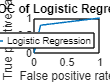


% Plot the ROC Curve
plot(X,Y)
hold off
legend('Logistic Regression','Location','SE');
xlabel('False positive rate'); ylabel('True positive rate');
title('ROC of Logistic Regression');

-     **Naive Bayes Classifier**

Cross_Validation = cvpartition(Y_QSAR_new, "KFold", 5); % Initialize Cross Validation
accuracy = zeros(Cross_Validation.NumTestSets, 1); % Initialize 5*1 cell for accuracy measurement
model_each_fold = cell(Cross_Validation.NumTestSets, 1); % Initialize cell array to store models

true_labels = []; % Initiate true label cell
predicted_scores = []; % Initiate predicted score cell

for i = 1:Cross_Validation.NumTestSets
    indices_train = Cross_Validation.training(i); % Divide each data set for training and test based on its fold
    indices_test = Cross_Validation.test(i); % Divide each data set for training and test based on its fold
    
    Feature_training = X_QSAR_new(indices_train, :); % Define Training fold for Features
    Label_training = Y_QSAR_new(indices_train, :); % Define Training fold for labels
    
    Feature_test = X_QSAR_new(indices_test, :); % Define Test fold for features
    Label_test = Y_QSAR_new(indices_test, :); % Define Test fold for labels
    
    mdl = fitcnb(Feature_training, Label_training); % Initialize Bayes Classifier
    
    [Label_pred,score] = predict(mdl, Feature_test);  % Predict the label from correspond model
     
    accuracy(i) = sum(Label_pred == Label_test) / length(Label_test); % Calculate the model accuracy
    model_each_fold{i} = mdl; % Store the model in model_each_fold

    disp(['For fold ', num2str(i),',', ' Accuracy: ', num2str(accuracy(i))]); % Display the accuracy in each fold 
end

For fold 1, Accuracy: 0.52857
For fold 2, Accuracy: 0.56872
For fold 3, Accuracy: 0.58294
For fold 4, Accuracy: 0.55238
For fold 5, Accuracy: 0.57619


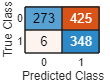


[~, idx] = max(accuracy); % Choose the Best Model with the highest accuracy in each fold
accuracy_model = max(accuracy); % Choose the model with the highest accuracy
bestModel = model_each_fold{idx}; % Retrieve the best model

[Y_pred_2,score] = predict(bestModel, X_QSAR_new); % Predict the data label using model 
predicted_scores = score(:,2); % retrieve the probabilties of "1"

cm = confusionchart(Y_QSAR_new,Y_pred_2); % Initialize confusion matrix 


disp(['Highest Accuracy of Naive Bayes model: ', num2str(accuracy_model)]) % display the highest accuracy of Naive Bayes

Highest Accuracy of Naive Bayes model: 0.58294



True_Positive_NB = sum((Y_pred_2 == 1) & (Y_QSAR_new == 1)) % Define True Positive

True_Positive_NB = 348

False_Positive_NB = sum((Y_pred_2 == 1) & (Y_QSAR_new == 0)) % Define False Positive

False_Positive_NB = 425

True_Negative_NB = sum((Y_pred_2 == 0) & (Y_QSAR_new == 0)) % Define True Negative

True_Negative_NB = 273

False_Negative_NB = sum((Y_pred_2 == 0) & (Y_QSAR_new == 1)) % Define False Negative

False_Negative_NB = 6


Sensitivity_QSAR_NB = True_Positive_NB/(True_Positive_NB+False_Negative_NB) % Define Sensitivity

Sensitivity_QSAR_NB = 0.9831

Specificity_QSAR_NB = True_Negative_NB/(True_Negative_NB+False_Positive_NB) % Define Specificity

Specificity_QSAR_NB = 0.3911


[X,Y,T,AUC] = perfcurve(Y_QSAR_new, predicted_scores, 1); % Establish ROC Curve with retrieving Thereshold and AUC

disp(['Area Under the Curve of Naive Bayes: ', num2str(AUC)]) % Display the AUC for Naive Bayes Clasifier

Area Under the Curve of Naive Bayes: 0.73254


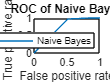


% Plot the ROC Curve    
plot(X,Y)
hold off
legend('Naive Bayes','Location','SE');
xlabel('False positive rate'); ylabel('True positive rate');
title('ROC of Naive Bayes');